Aby to fungovalo, musí se přidat cesta, zároveň zavedeme nápovědu (sta čí spustit na začátku relace jednou)

addpath(genpath('C:\Fyzing\Baka\MATLAB\MNPBEM17'));
run('C:\Fyzing\Baka\MATLAB\MNPBEM17/makemnpbemhelp.m')

clc 
clear all
close all

Set up the dielectric environment:

%  options for BEM simulation
op = bemoptions( 'sim', 'stat' );
%  table of dielectric functions
epstab = { epsconst( 1), epstable( 'silver.dat' ) };

epsconst(1) ... dielectrc function of vacuum

p1 = trirod( 10, 30, [ 20, 10, 20 ] );
p1 = rot(p1, 90, [0,1,0])

p1 = particle : 
     verts: [694×3 double]
     faces: [703×4 double]
    interp: 'flat'


p1 = shift( p1, [ 0, 10 ,10 ] );

p2 = trirod( 10, 30, [ 20, 10, 20 ] );
p2 = rot(p2, 90, [1,0,0])

p2 = particle : 
     verts: [694×3 double]
     faces: [703×4 double]
    interp: 'flat'


p2 = shift( p2, [ 10, 0, 0 ] );

n1 for the circumference of the rod, n2 for the polar angles of the rod caps, n3 for the cylinder-shaped middle part of the rod, and

p = comparticle( epstab, { p1, p2 }, [ 2, 1; 2, 1 ], 1, 2, op );

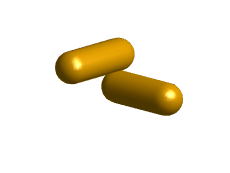

clf
plot( p);
xlim("auto")
ylim("auto")
zlim("auto")
view([-46.3 16.0])

%plot( p, 'EdgeColor', "b");
% plot( p, 'EdgeColor', 'b', 'nvec', 1 );

%  set up BEM solver
% bem = bemsolver( p, op );
% [ ene, ur] = plasmonmode( p, 10 )

nev = 50

nev = 50

bemeig = bemstateig(p, op, 'nev', nev);
% from the eigensolution, we can get the corresponding pseudocharges on the
% surface corresponding to different eigenmodes
eigencharges = bemeig.ur

eigencharges =   -0.0306 + 0.0000i   0.0051 + 0.0000i   0.0053 + 0.0000i  -0.0338 + 0.0000i  -0.0003 + 0.0000i   0.0004 + 0.0000i   0.0172 + 0.0000i  -0.0040 + 0.0000i  -0.0198 + 0.0000i  -0.0004 + 0.0000i  -0.0113 + 0.0000i   0.0041 + 0.0000i  -0.0070 + 0.0000i   0.0115 + 0.0000i   0.0054 + 0.0000i   0.0255 + 0.0000i  -0.0016 + 0.0000i  -0.0130 + 0.0000i   0.0143 + 0.0000i  -0.0154 + 0.0000i   0.0076 + 0.0000i  -0.0049 + 0.0000i   0.0056 + 0.0000i   0.0103 + 0.0127i   0.0103 - 0.0127i   0.0185 + 0.0000i  -0.0095 + 0.0000i   0.0435 + 0.0000i  -0.0302 + 0.0000i  -0.0101 - 0.0106i  -0.0101 + 0.0106i  -0.0501 + 0.0000i   0.0558 + 0.0000i   0.0322 + 0.0000i  -0.0192 + 0.0000i  -0.0078 + 0.0000i  -0.0179 + 0.0000i  -0.0303 + 0.0000i  -0.0176 + 0.0000i   0.0009 + 0.0000i   0.0011 + 0.0000i   0.0016 + 0.0000i  -0.0013 + 0.0000i  -0.0406 + 0.0000i  -0.0159 + 0.0000i  -0.0308 + 0.0000i   0.0009 + 0.0000i  -0.0280 + 0.0000i  -0.0006 + 0.0000i   0.0024 + 0.0000i
  -0.0280 + 0.0000i   0.0027 + 0.0

eigenpseudolambdas = bemeig.ene %unit matrix with eigeneenrgies on diagonal

eigenpseudolambdas =   -6.2832 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -6.2745

pfacepos = p.pos

pfacepos =    14.9494   10.0940    9.4369
   14.8113   10.2093    8.7458
   14.5143   10.3418    7.9520
   14.0802   10.4638    7.2204
   13.5221   10.5718    6.5733
   12.8570   10.6624    6.0304
   12.1051   10.7329    5.6080
   11.2892   10.7811    5.3191
   10.4341   10.8056    5.1724
   14.9494   10.2717    9.4979


pfacearea = p.area

pfacearea =     0.1229
    0.3652
    0.5972
    0.8122
    1.0036
    1.1654
    1.2920
    1.3791
    1.4235
    0.1229




writematrix(eigencharges,"MY_PROJECTS\baka00\eigencharges.csv")
writematrix(eigenpseudolambdas,"MY_PROJECTS\baka00\eigenpseudolambdas.csv")
writematrix(pfacepos,"MY_PROJECTS\baka00\pfacepos.csv")
writematrix(pfacearea,"MY_PROJECTS\baka00\pfacearea.csv")

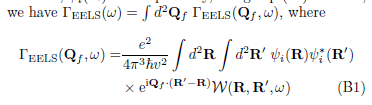

pfacepos =    14.9494   10.0940    9.4369
   14.8113   10.2093    8.7458
   14.5143   10.3418    7.9520
   14.0802   10.4638    7.2204
   13.5221   10.5718    6.5733
   12.8570   10.6624    6.0304
   12.1051   10.7329    5.6080
   11.2892   10.7811    5.3191
   10.4341   10.8056    5.1724
   14.9494   10.2717    9.4979


pfacearea =     0.1229
    0.3652
    0.5972
    0.8122
    1.0036
    1.1654
    1.2920
    1.3791
    1.4235
    0.1229




numofpoints = 51

numofpoints = 51

ranger = 30

ranger = 30

xlin = linspace(-ranger, ranger, numofpoints);
ylin = linspace(-ranger, ranger, numofpoints);
[X, Y] = meshgrid(xlin,ylin);

omega = 1e9

omega = 1.0000e+09

v = 0.446 * 3e8

v = 133800000

potentials = cell(nev,1);

for n = 1:nev
    potentials(n) = 0 * X;
for s = 1:length(pfacearea)
    potentials(n) = potentials(n) + 2  * pfacearea(s) * eigencharges(s, n) * exp( -1j * omega / v * pfacepos(s,3)) * besselk(0, omega / v  * sqrt( (X - pfacepos(s,1))^2 + (Y - pfacepos(s,2))^2 ) )
end 
end

Conversion to cell from double is not possible.

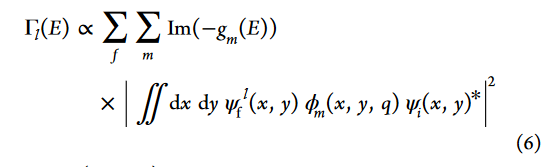


diameter = 30
numofpoints = 50

for n = 1:5
                %desired mode index   
sig = compstruct(p,enei);         %compstruct object that can be fed to the "potential" function
sig.sig = bemeig.ur(:,nEigenmode);    %replacement of an ordinary charge by the pseudocharge

%% plot of the potential using the compoint object
% x = linspace( - diameter, diameter, numofpoints );
% z = linspace( - diameter, diameter, numofpoints );
% [X, Z] = ndgrid( x, z );
% ysel = 0; % coordinate of the selected y plane
% Y = ones( size(X) )*ysel;
% 
% pt = compoint( p, [ X(:), Y(:), Z(:) ], 'medium', 1, 'mindist', 1e-6 );      
% g = greenfunction( pt, p, op );
% pot = potential( g, sig );
% 
% phiOut = zeros(size(X));
% tmp = struct(pt);
% SubIndex = tmp.ind{1};
% phiOut(SubIndex) = pot.phi1;
% 
% pt = compoint( p, [ X(:), Y(:), Z(:) ], 'medium', 2, 'mindist', 1e-6 );      
% g = greenfunction( pt, p, op );
% pot = potential( g, sig );
% 
% phiIn = zeros(size(X));
% tmp = struct(pt);
% SubIndex = tmp.ind{2};
% phiIn(SubIndex) = pot.phi1;
% 
% phiInOut = phiIn + phiOut;
% 
% figure(2);
% hold off;
% imagesc( x, z, phiInOut ); 
% colorbar;  colormap jet;
% xlabel( 'x (nm)' );
% ylabel( 'z (nm)' );
% set( gca, 'YDir', 'norm' );
% axis equal tight

%% extracting potential in 3D
x = linspace( - diameter, diameter, numofpoints );
y = linspace( - diameter, diameter, numofpoints );
z = linspace( - diameter, diameter, numofpoints );
[X, Y, Z] = ndgrid( x, y, z );

pt = compoint( p, [ X(:), Y(:), Z(:) ], 'medium', 1, 'mindist', 1e-6 );      
g = greenfunction( pt, p, op );
pot = potential( g, sig );

phiOut = zeros(size(X));
tmp = struct(pt);
SubIndex = tmp.ind{1};
phiOut(SubIndex) = pot.phi1;

pt = compoint( p, [ X(:), Y(:), Z(:) ], 'medium', 2, 'mindist', 1e-6 );      
g = greenfunction( pt, p, op );
pot = potential( g, sig );

phiIn = zeros(size(X));
tmp = struct(pt);
SubIndex = tmp.ind{2};
phiIn(SubIndex) = pot.phi1;

phiInOut = phiIn + phiOut;

B=reshape(phiInOut,numofpoints,numofpoints*numofpoints);
fname = sprintf('MY_PROJECTS/potential_schiralnitycky_eig%d.csv', nEigenmode);
%open(fname, 'w')
save(fname,'B','-ascii')

figure(nEigenmode)
plot(p, sig.sig)

end